# Soluciones Numéricas para el Sistema RLC

26 de mayo de 2023

Alan Michel Carrasco Meza | José Iván Bravo Castro

En este *live script* se documentan los códigos de Matlab utilizados para la resolución de la ecuación en diferencias mediante el método de recursividad y la aproximación de sistemas en tiempo continuo desde tiempo discreto. Estos códigos no son de autoría propia, sino que fueron proporcionados por el profesor José Alberto Arellano Figueroa. Lo que sus servidores realizaron fue la documentación del código y su utilización para resolver la práctica no.4: *Transformada Z y sus aplicaciones a sistemas de tiempo discreto,  *del laboratorio de análisis de sistemas y señales.

El sistema que se analizó fue un circuito RLC, cuyo comportamiento se puede modelar por la siguiente expresión.


$$\frac{d^2V_c(t)}{dt^2} + \frac{R}{L} \frac{dV_c(t)}{dt} + \frac{1}{LC}V_c(t) = \frac{1}{LC}V_g(t)$$


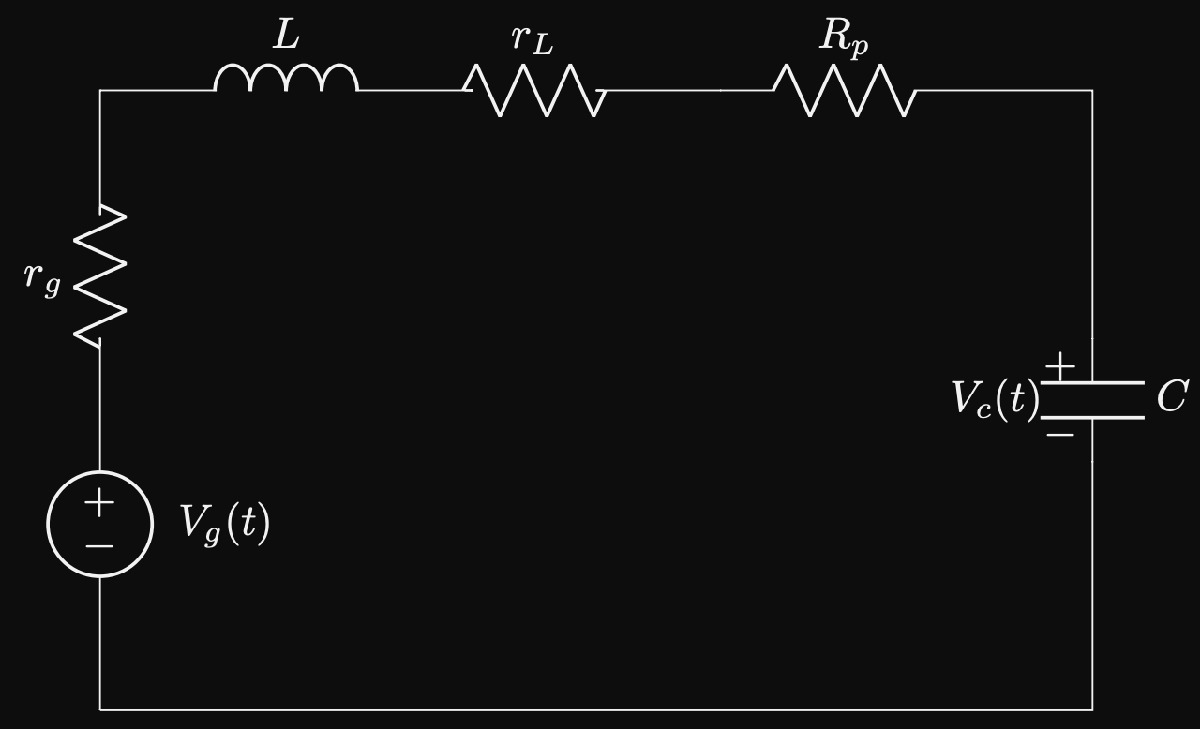

La ecuación en diferencias equivalente al modelo en tiempo continuo es la siguiente.


$$C_2V_c[n-2] - C_1V_c[n-1] + V_c[n] = d_0V_g[n]$$


En la siguiente sección se explica cómo se obtuvieron C1, C2 y d0. 

## Solución de la Ecuación en Diferencias Finitas mediante Método de Recursividad

La primera actividad que se solicita en la práctica es la discretización del sistema para poder aproximar su solución mediante el método de recursividad. Para esto se utilizó la forma de la ecuación en diferencias vista en el párrafo anterior, donde los coeficientes se calcularon utilizando la función en vivo *constantes.mlx.*

   0.428571428571429   0.142857142857143   0.714285714285714



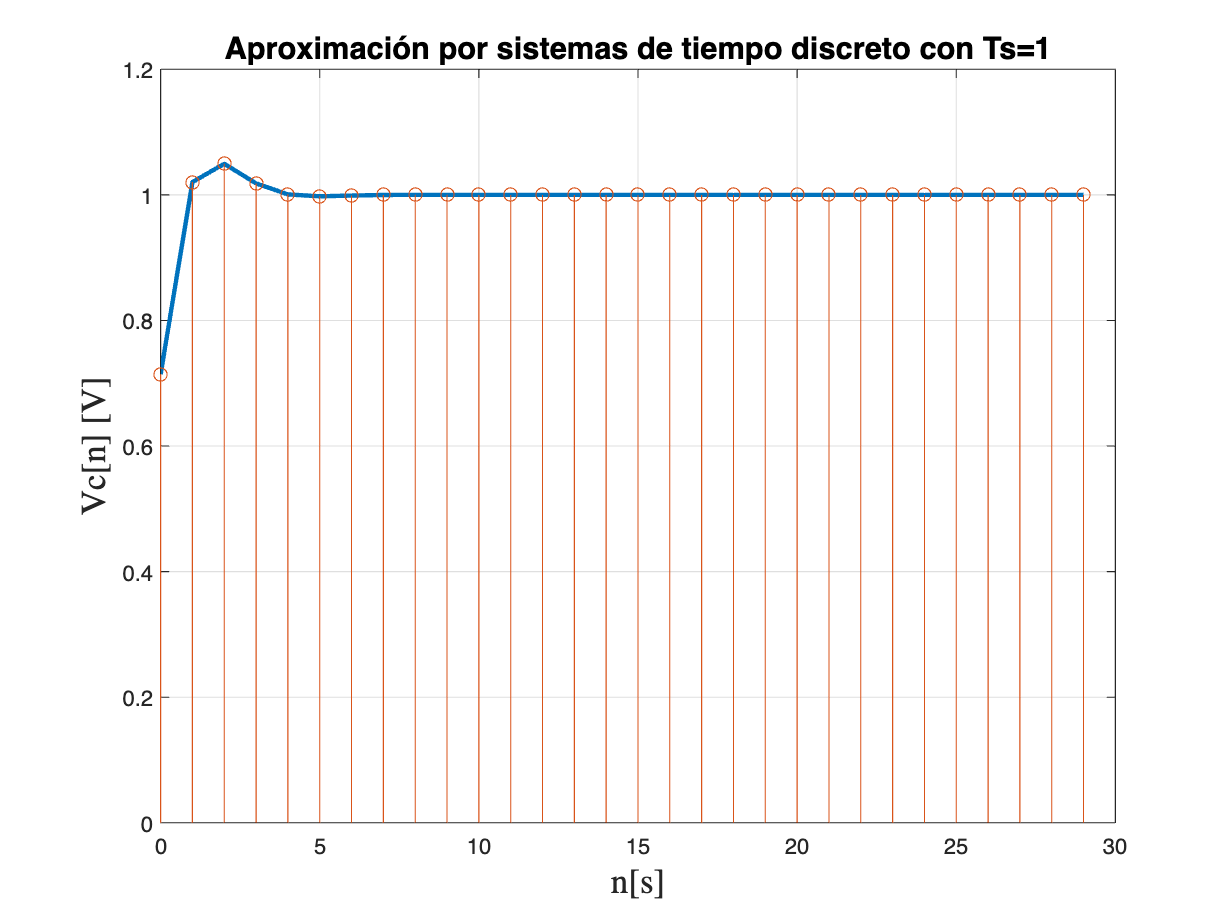

   1.826086956521739   0.869565217391304   0.043478260869565



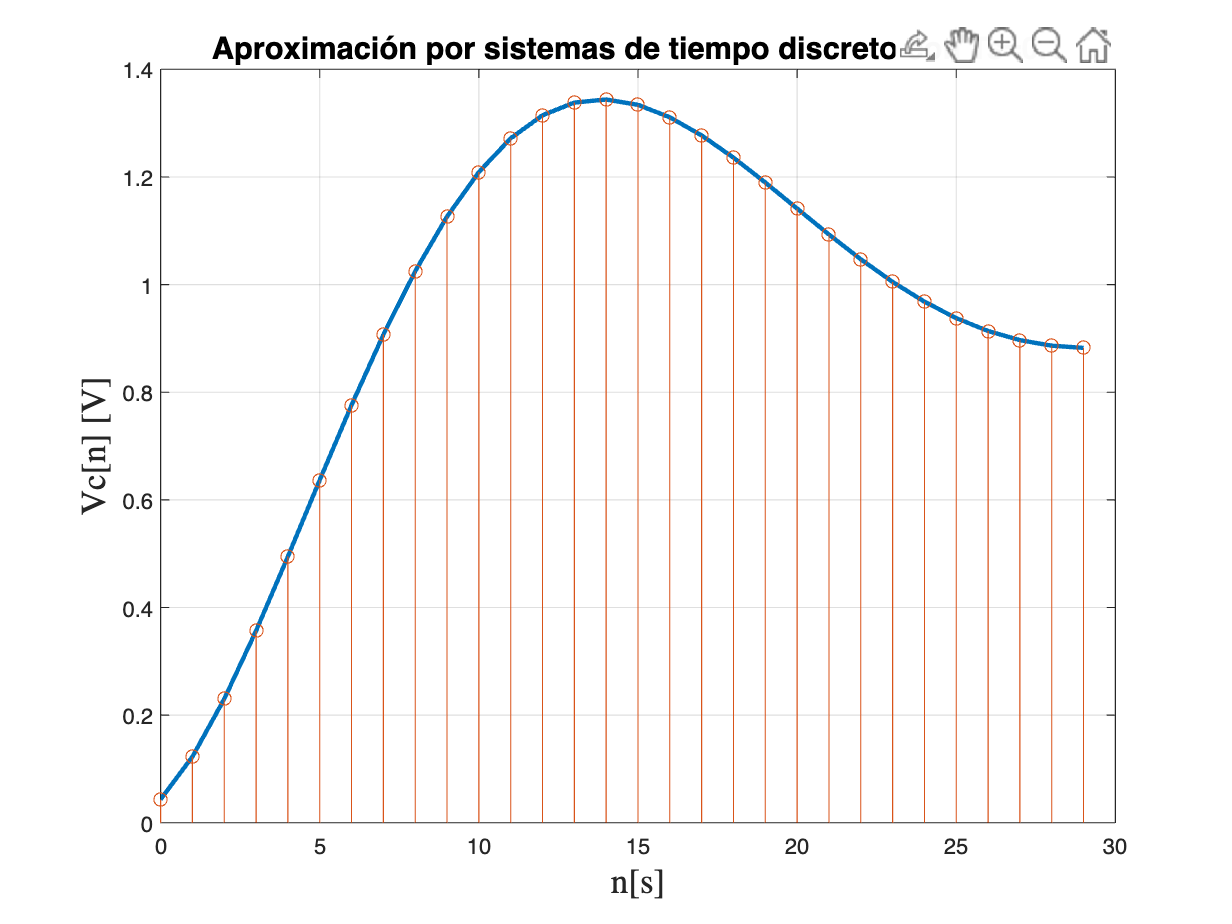

   1.989114299851559   0.989609104403761   0.000494804552202



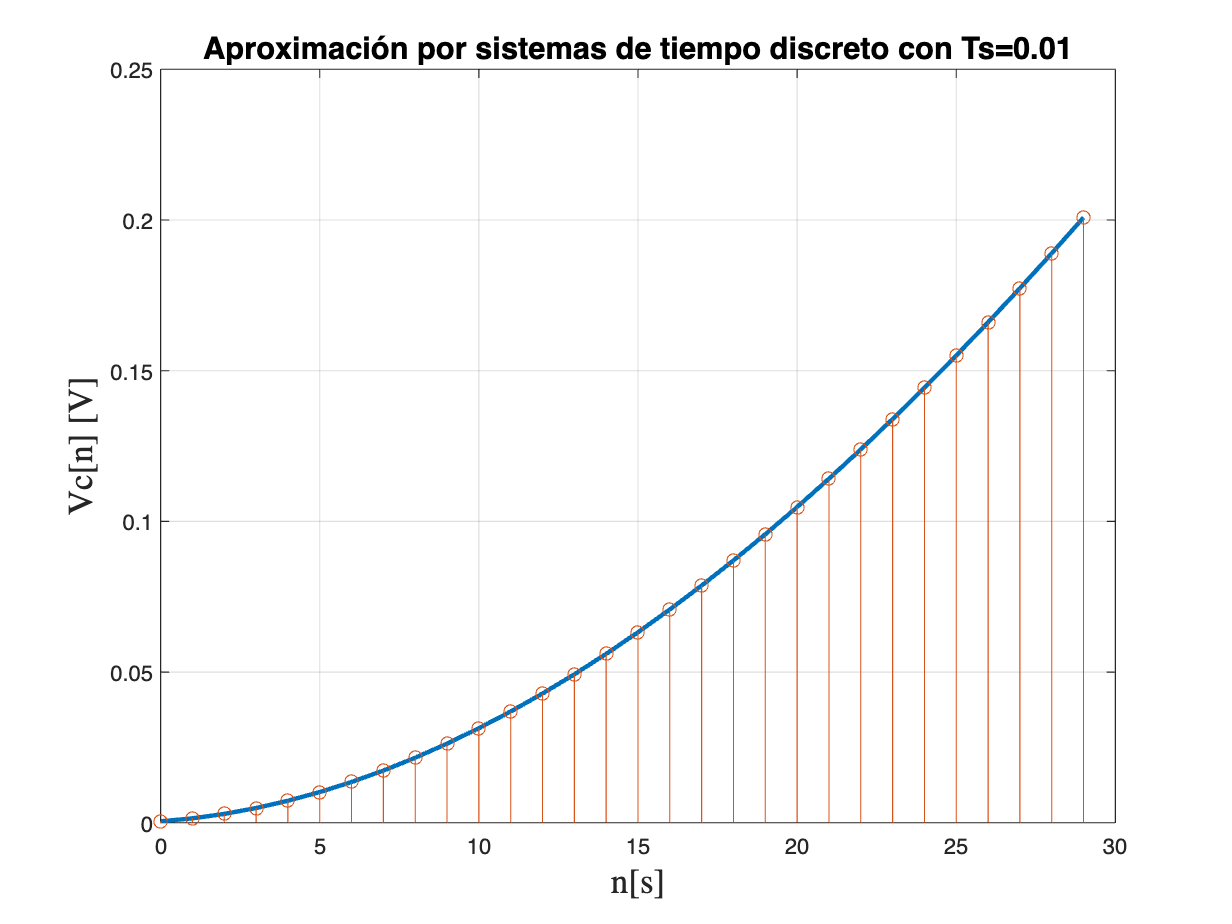

   1.998991014030899   0.998996009010944   0.000004994980045



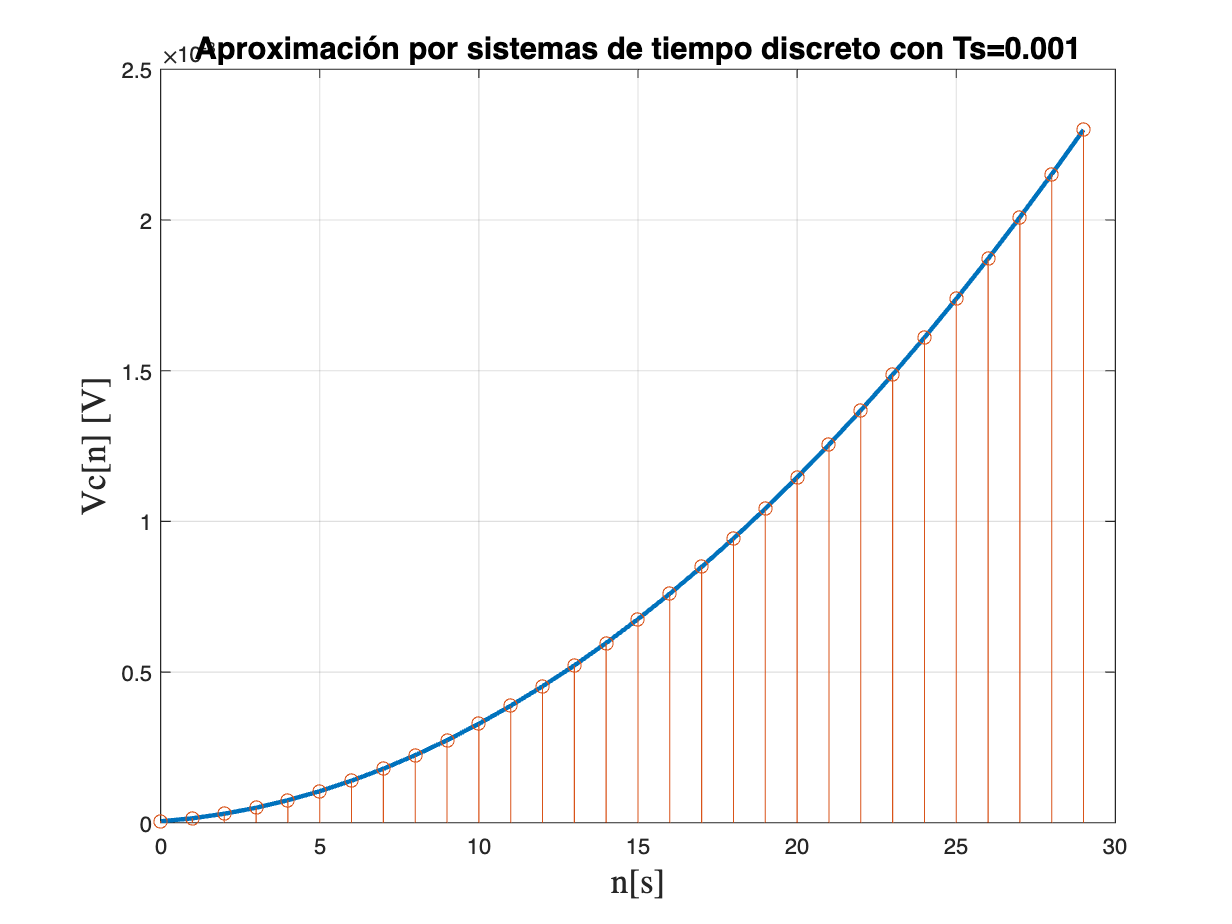

   1.999899910014004   0.999899960009001   0.000000049994998



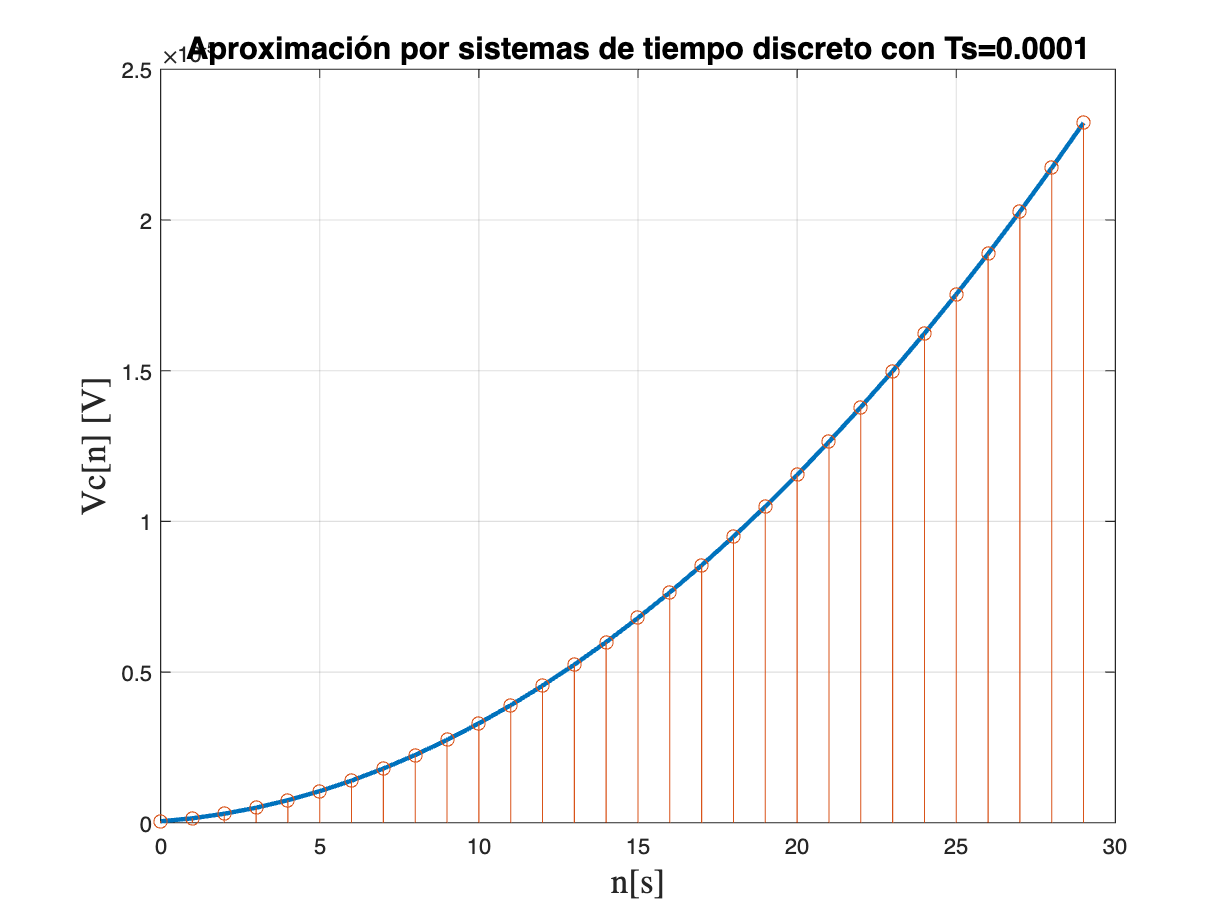

   1.999989999100014   0.999989999600009   0.000000000499995



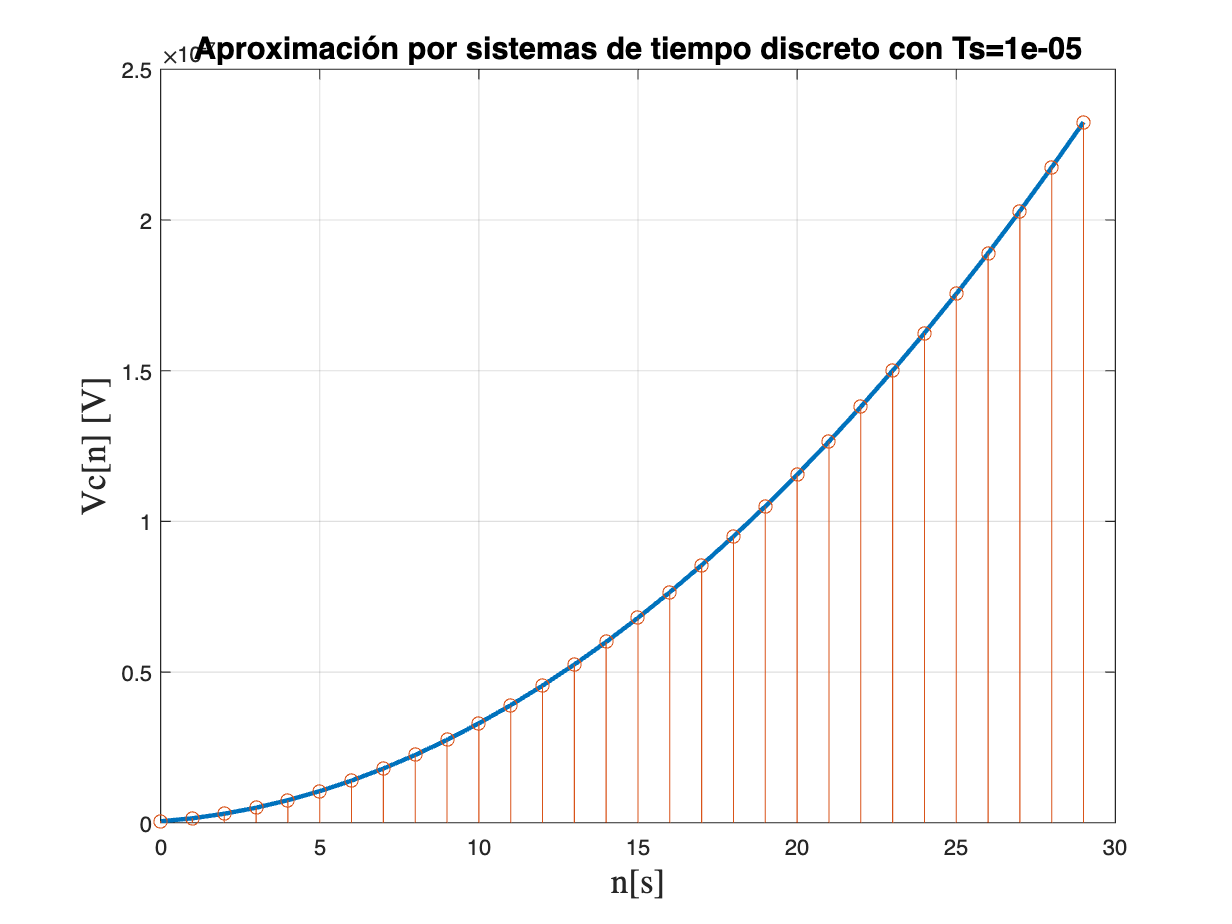

m=30;   % Número de muestras tomadas
R=1;    % Resistencia equivalente del circuito
L=1;    % Valor de inductancia
C=1/5;  % Valor de capacitancia

% Coeficientes del modelo en tiempo continuo
a1=R/L;     % Definición del coeficiente a1
a0=1/(L*C); % Definición del coeficiente a0
b0=1/(L*C); % Definición del coeficiente b0

% Declaración de vectores
Vc=zeros(); % Vector de ceros para el voltaje del capacitor
n=zeros();  % Vector de ceros para el valor de n

% Método numérico para la discretización 
for p=1:6   % Genera los tiempos de muestreo de Ts=1 disminuyendolo en 0.1 hasta 0.0001
    figure  % Genera un marco para las gráficas
    Ts=10/10^p; % Define el tiempo de muestreo para esta iteración
    [C1,C2,d0]=constantes(a1,a0,b0,Ts); % Se calculan los ceoficientes llamando al live function constantes.mlx
    disp([C1,C2,d0]) % Se imprimen los coeficientes del modelo en tiempo discreto
    
    for c=1:m % Se crea Vcn por el método de recurrencia
        % Ecuación de recurrencia:
        Vc(c)=voltaje_capacitor(c-1,C1,C2,d0,1); % Se llama la live function voltaje_capacitor.mlx
        n(c)=c-1; % valores de n asociados a cada valor de Vc
    end

    % A partir de aquí son puros comandos para graficar
    format long
    Vc;
    plot(n,Vc,'LineWidth',2)
    hold on
    stem(n,Vc) 
    grid on
    hold off
    xlabel('n[s]',FontSize=16,Interpreter='latex')
    ylabel('Vc[n] [V]',FontSize=16,Interpreter='latex')
    title(['Aproximación por sistemas de tiempo discreto con Ts=',num2str(Ts)],'FontSize',14)
end

## Aproximación de Sistemas de Tiempo Continuo Por Tiempo Discreto

%Grafica de la Solución a la ecuación diferencial de la Actividad 1 del
%Voltaje en el Capacitor en el Sistema de 2do Orden
%d^2Vc(t)/dt^2+(R/L)dVc(t)/dt+(1/LC)Vc(t)=(1/LC)Vg(t)
%R/L=1 1/LC=5 

%Función de Transferencia en tiempo continuo
R=1; L=1; C=1/5;        % Parametros
num=(1/(L*C));          % Coeficientes de entrada
den=[1 R/L 1/(L*C)];    % Coeficientes de salida
Hs=tf(num,den)          % Función de transferencia en tiempo continuo

Hs =
 
       5
  -----------
  s^2 + s + 5
 
Continuous-time transfer function.



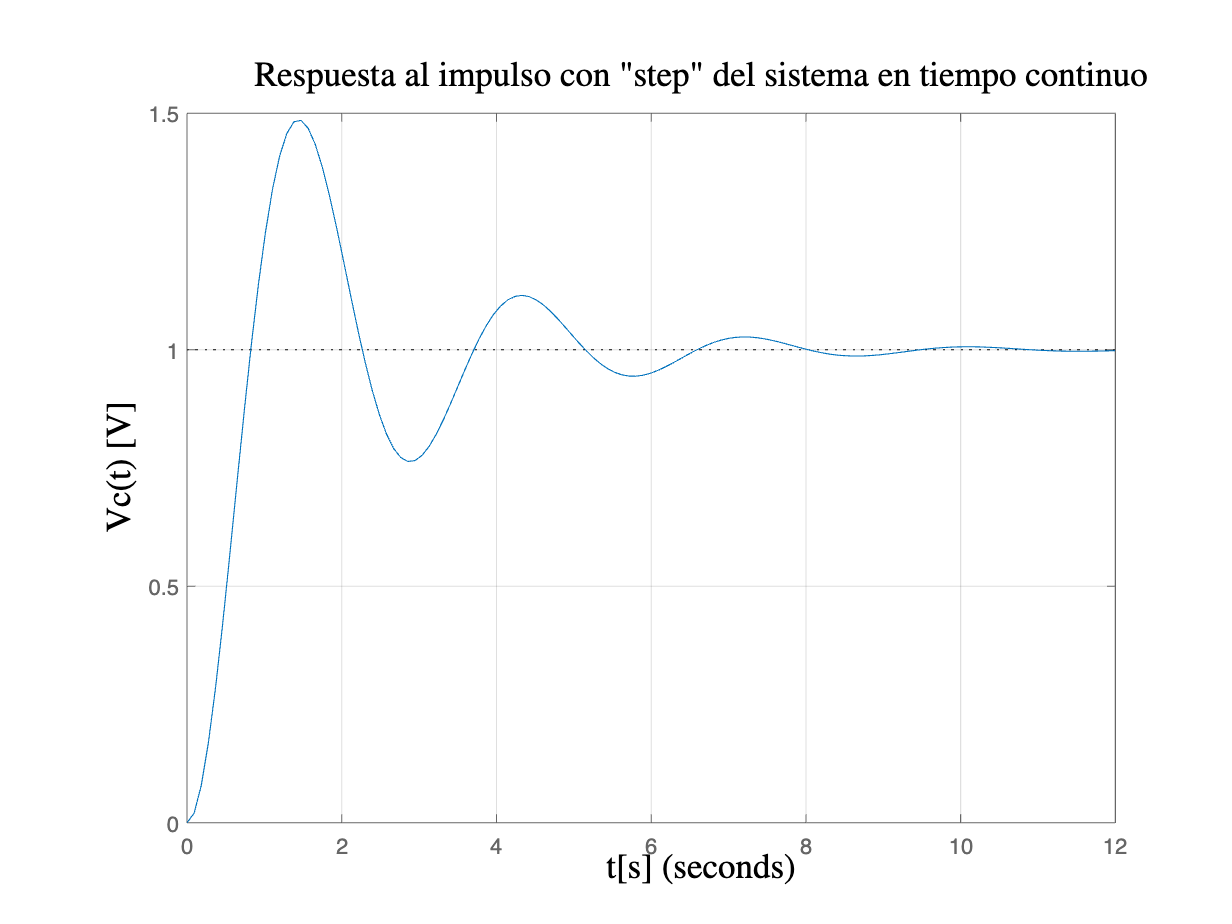

step(Hs)    % Respuesta al escalón

% A partir de aquí son puros comandos para graficar
grid on
xlabel('t[s]',FontSize=16,Interpreter='latex')
ylabel('Vc(t) [V]',FontSize=16,Interpreter='latex')
title('Respuesta al impulso con "step" del sistema en tiempo continuo','FontSize',16,Interpreter='latex')

Hz =
 
     1.233 z + 0.8288
  -----------------------
  z^2 + 0.6936 z + 0.3679
 
Sample time: 1 seconds
Discrete-time transfer function.



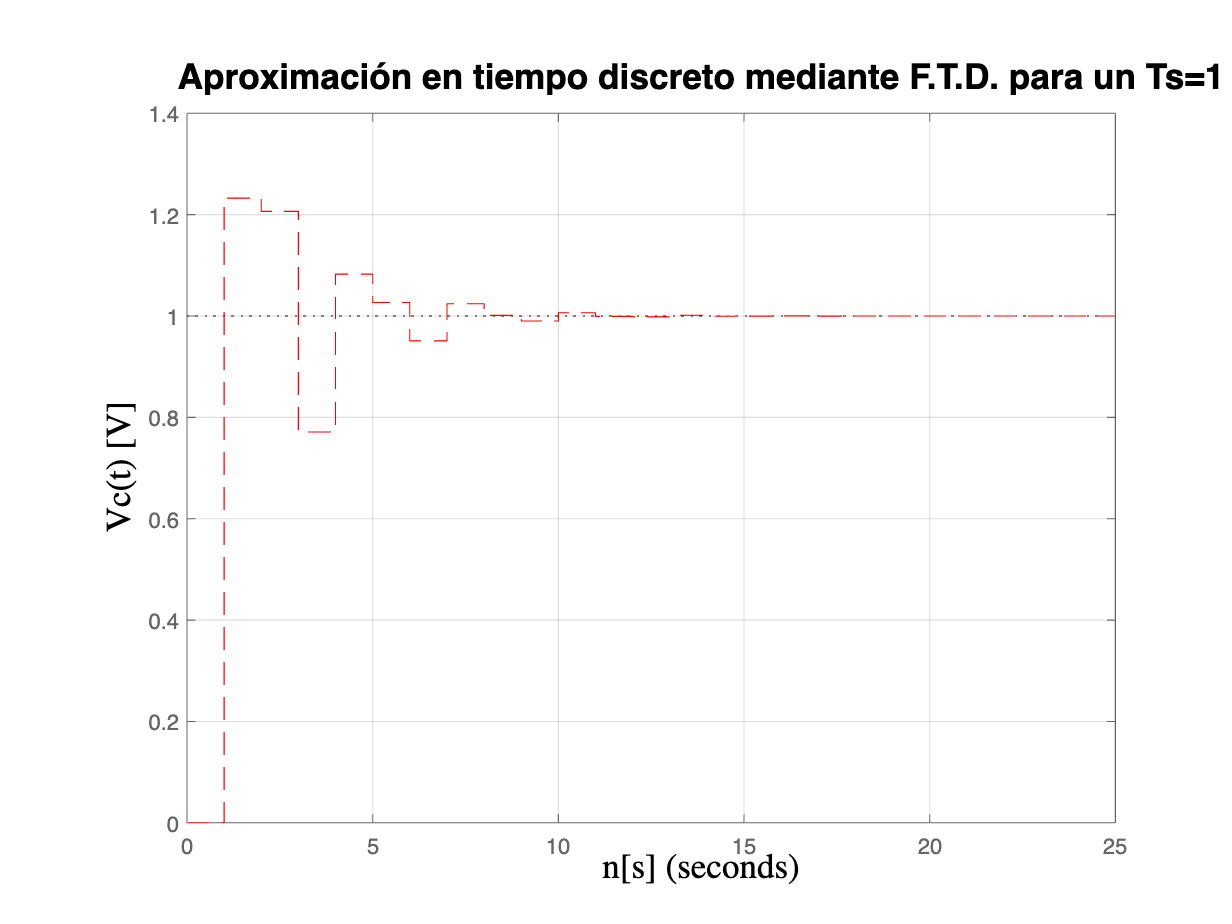

Hz =
 
    0.02409 z + 0.0233
  ----------------------
  z^2 - 1.857 z + 0.9048
 
Sample time: 0.1 seconds
Discrete-time transfer function.



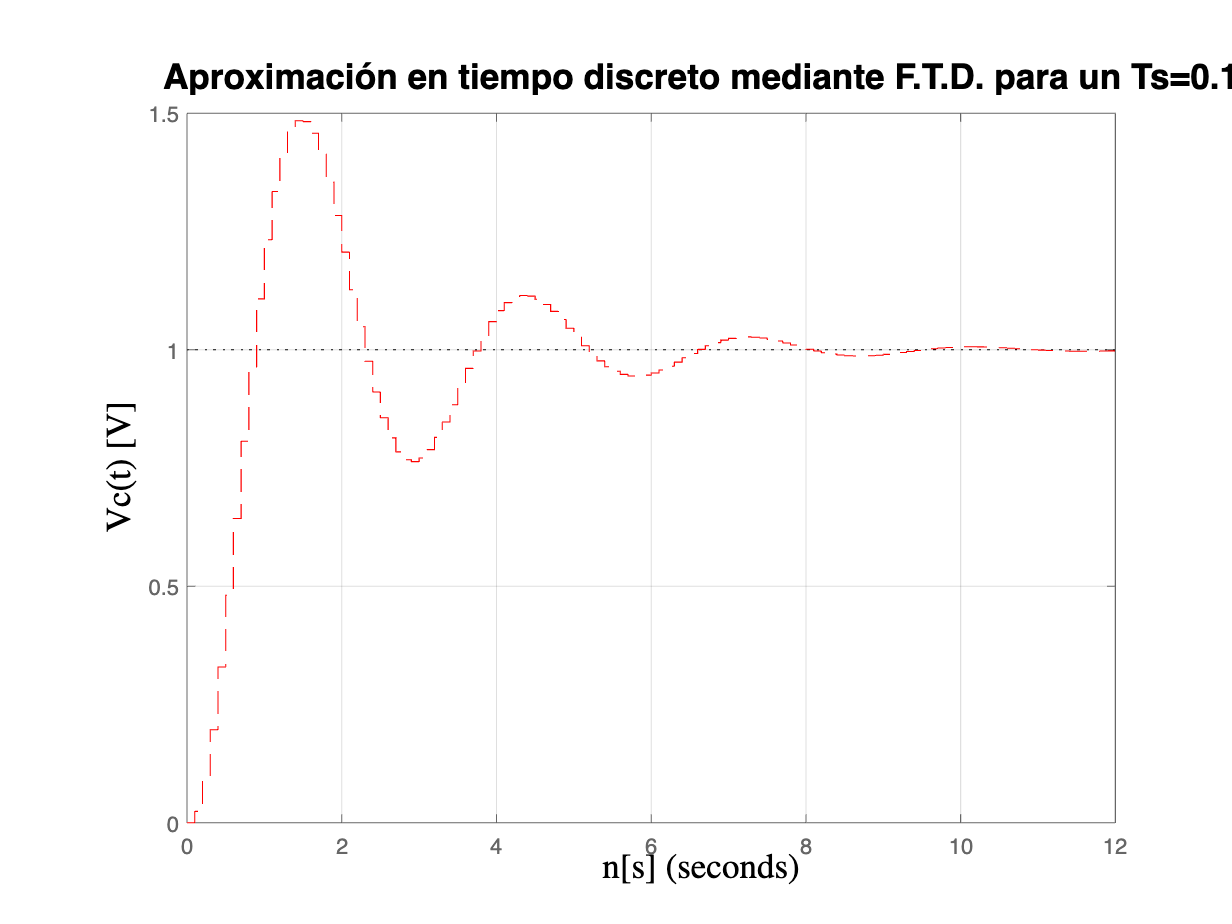

Hz =
 
  0.0002492 z + 0.0002483
  -----------------------
    z^2 - 1.99 z + 0.99
 
Sample time: 0.01 seconds
Discrete-time transfer function.



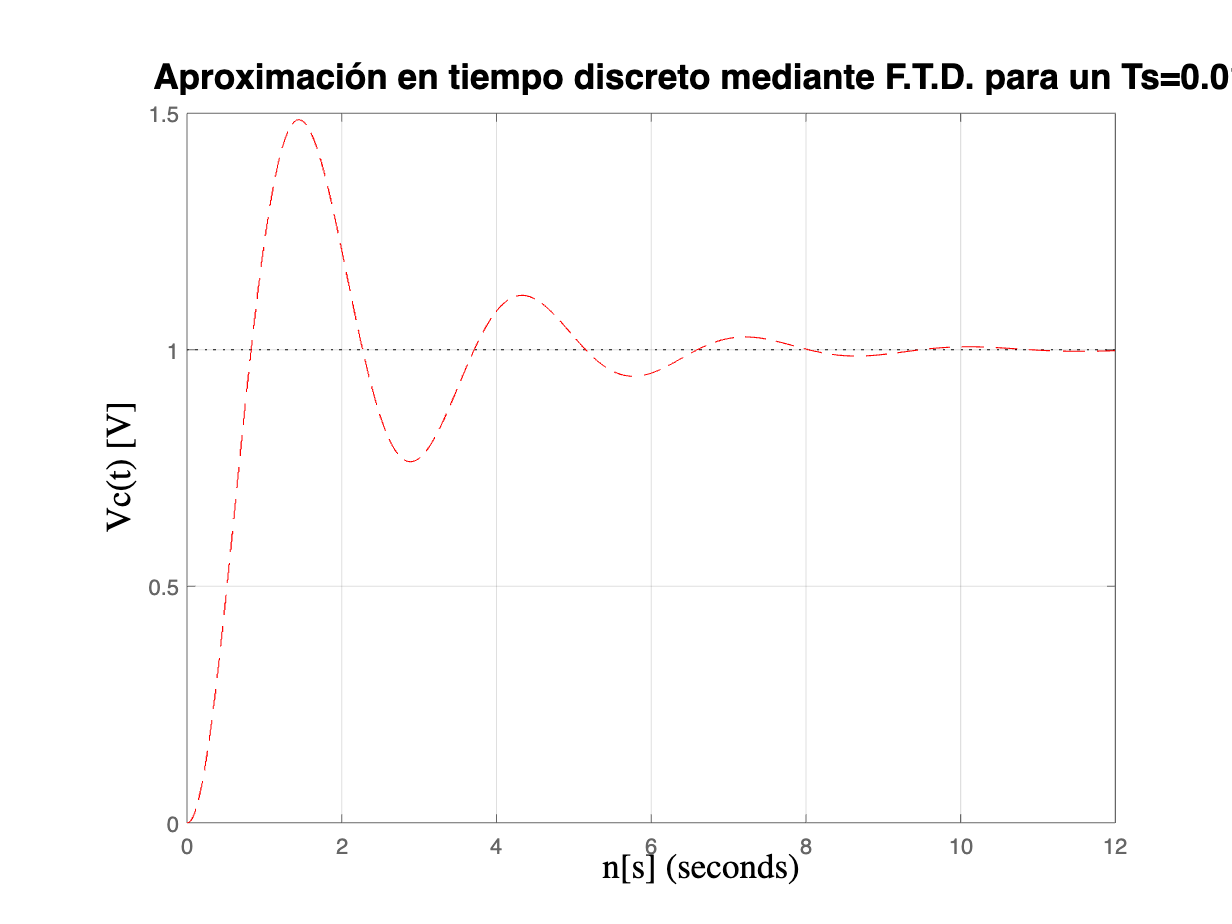

Hz =
 
  2.499e-06 z + 2.498e-06
  -----------------------
   z^2 - 1.999 z + 0.999
 
Sample time: 0.001 seconds
Discrete-time transfer function.



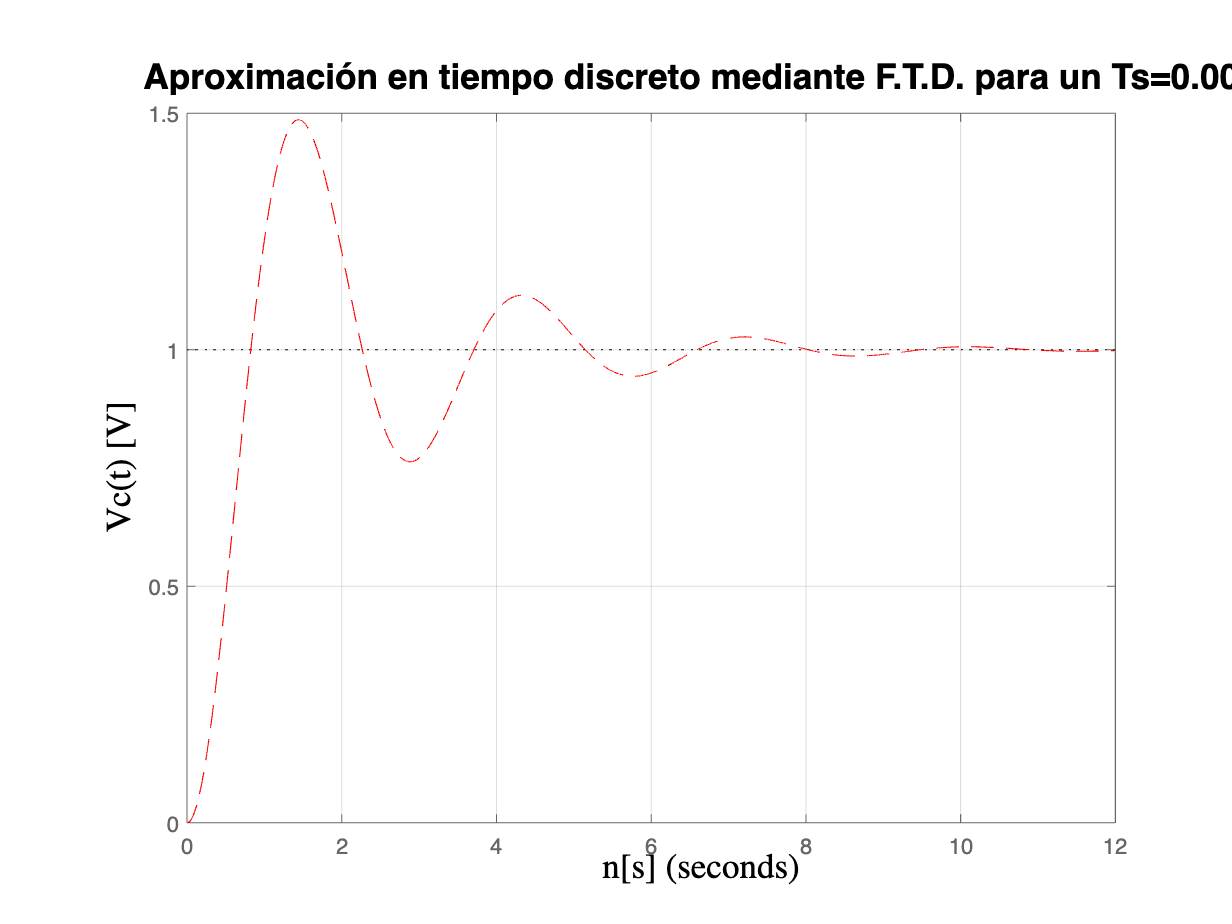

Hz =
 
  2.5e-08 z + 2.5e-08
  -------------------
  z^2 - 2 z + 0.9999
 
Sample time: 0.0001 seconds
Discrete-time transfer function.



% Función de transferencia en tiempo discreto con los distintos tiempos de
% muestreo a partir de la F.T. de tiempo continuo
for p=1:5
    Ts=10/10^p;         % Genera el tiempo de muestreo para esa iteración
    Hz=c2d(Hs,Ts,'zoh') % F.T en discreta
    figure
    step(Hz,'r --')     % respuesta al escalon

    % Puros comandos de graficación
    grid on
    hold on
    xlabel('n[s]','FontSize',16,Interpreter='latex')
    ylabel('Vc(t) [V]',FontSize=16,Interpreter='latex')
    title(['Aproximación en tiempo discreto mediante F.T.D. para un Ts=',num2str(Ts)],FontSize=16)
end

## Comparación de la Respuesta al Impulso en Tiempo Continuo contra Tiempo Discreto

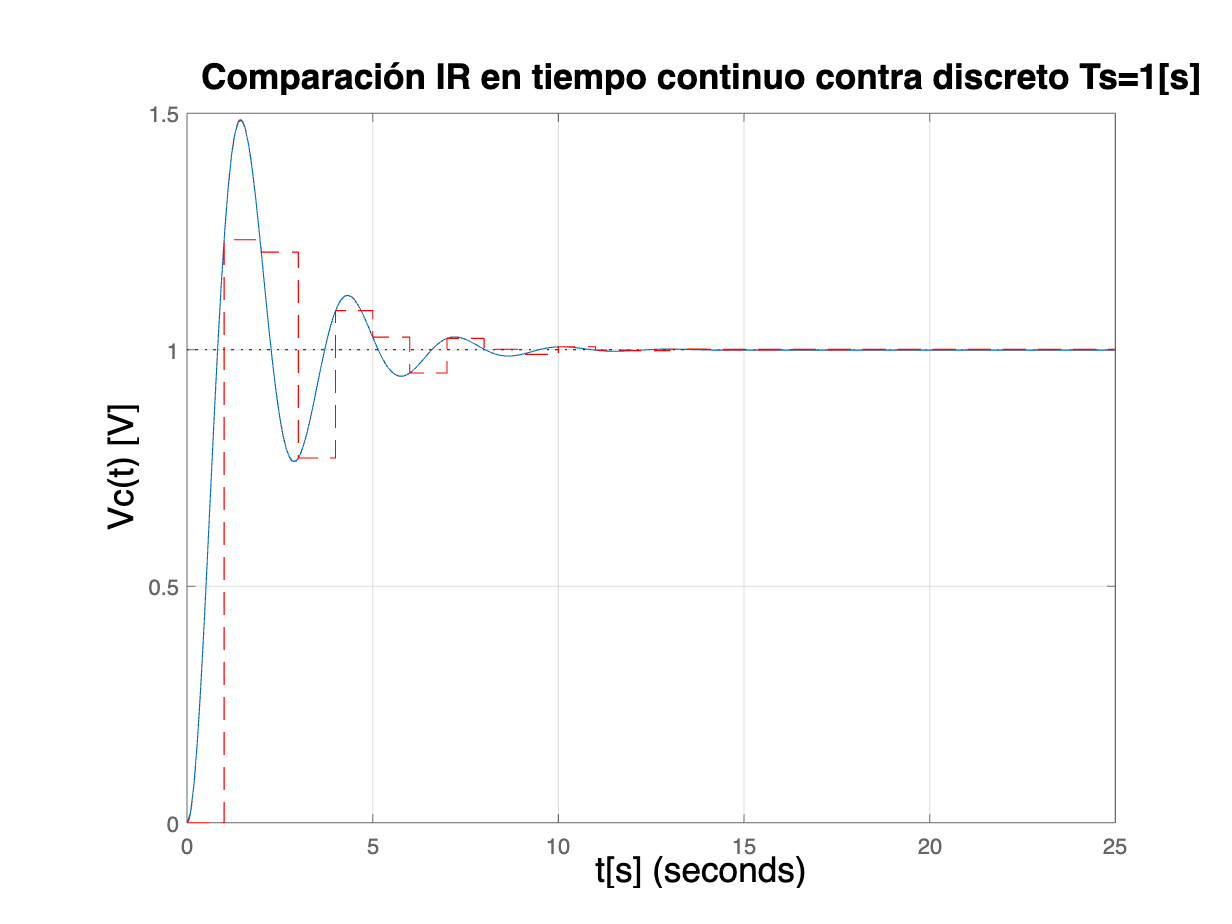

% Ts = 1
% Tiempo continuo
Hs=tf(num,den); % F.T.
step(Hs)        % Respuesta al escalón
grid on
hold on
xlabel('t[s]',FontSize=16,Interpreter='latex')
ylabel('Vc(t) [V]',FontSize=16,Interpreter='latex')
title('Comparación IR en tiempo continuo contra discreto Ts=1[s]','FontSize',16,Interpreter='latex')%Ponle título

% Tiempo discreto
Ts = 1; % Periodo de muestreo
Hz=c2d(Hs,Ts,'zoh'); % Función de transferencia discreta
step(Hz,'r --'); % Respuesta al escalón
hold off

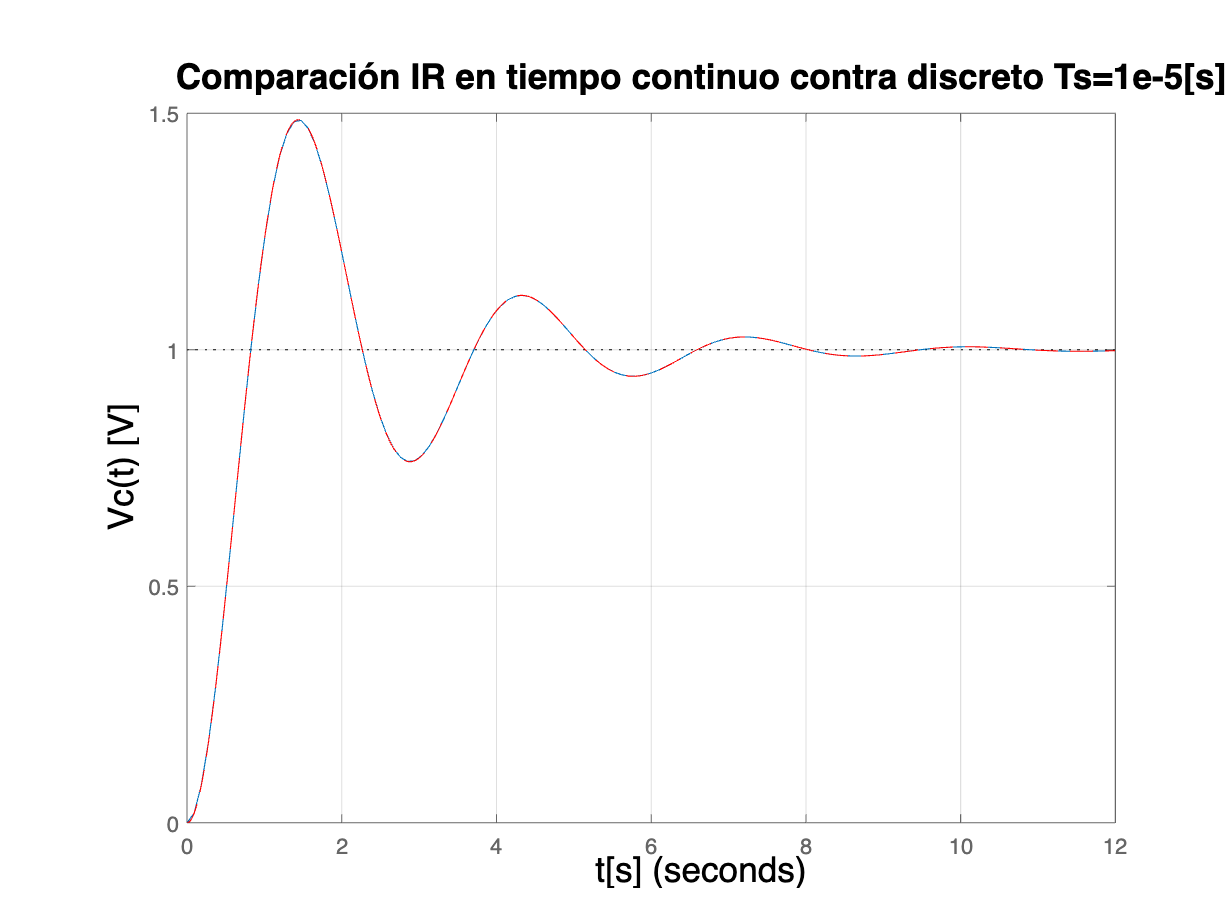

% Ts = 1e-5[s])
% Tiempo continuo
Hs=tf(num,den); % F.T.
figure
step(Hs) % Respuesta al escalón
grid on
hold on
xlabel('t[s]',FontSize=16,Interpreter='latex')
ylabel('Vc(t) [V]',FontSize=16,Interpreter='latex')
title('Comparación IR en tiempo continuo contra discreto Ts=1e-5[s]','FontSize',16,Interpreter='latex')%Ponle título

% Tiempo discreto
Ts = 10/10^5; % Periodo de muestreo
Hz=c2d(Hs,Ts,'zoh'); % F.T discreta
step(Hz,'r --'); % Respuesta al escalón